# Project 3 - Matlab - Covid-19 Pandemic

*Pablo Martínez, Oriol Bustos*

In this third and last project..

%addpath(['C:/Users/oriol/Escritorio/[4] Estudios/[1] EBM/[1.S8]/[4.1.2] DPVL/data_lab/Project 3/Pandemic/'])
%addpath(tudirectorio)

## 1. Density effect

d = linspace(0.01, 0.5, 4);
plot_epidemic_curves_check = false
for i=1:4
    result = Pandemic_Matlab_ex1(d(i), plot_epidemic_curves_check);
end
result

## 2. Create a movie

d = 0.01
plot_epidemic_curves_check = false
result = Pandemic_Matlab_ex2(d, plot_epidemic_curves_check);

movie(result.M)

## 3. The Rho number and Re-infections

Result = Pandemic_Matlab_ex3(Input, false);
infection_matrix = Result.infection_matrix;
% Finding the Rho number: 
Rho_vals = zeros(size(infection_matrix(1,:)));
Reinfections = zeros(size(infection_matrix(1,:)));
for i=1:length(infection_matrix(:,1))
    Rho_vals(1,i) = sum(infection_matrix(i,:));
    Reinfections(1,i) = sum(infection_matrix(:,i));
end
mean_val = mean(Rho_vals);
reinf_num = sum(Reinfections);
disp(mean_val);
disp(reinf_num);

## 4. Finding Regrothws

fcorrer para diferentes escenarios la curva de infectados y con findpeaks contar el numero de picos, si hay vairos hay regrowths

d = linspace(0.01, 0.5, 4);
confinement = [0, 1];
confined_pc_values = [50, 80];
combinations = [];

% generate combinations
for density = d
    for conf = confinement
        if conf == 0
            combinations = [combinations; density, 0, 1]; 
        else
            for confined_pc = confined_pc_values
                combinations = [combinations; density, 1, confined_pc];
            end
        end
    end
end
peakCounts = zeros(size(combinations, 1), 1);

for i = 1:size(combinations, 1)
    density = combinations(i, 1);
    conf = combinations(i, 2);
    confined_percent = combinations(i, 3);

    result = Pandemic_Matlab_ex4(density, false, conf, confined_percent);
    [peaks, ~] = findpeaks(result.infected);
    peakCounts(i) = numel(peaks);
end

disp('Combinations and their peak counts:');
for i = 1:size(combinations, 1)
    fprintf('Density: %.2f, Confinement: %d, Confined Percent: %d, Peaks: %d\n', ...
        combinations(i, 1), combinations(i, 2), combinations(i, 3), peakCounts(i));
end


## 5. Opening the Gaps

## 6. SIR Model

aaa

density = 0.2;

result = Pandemic_Matlab_ex6(density, false);
disp(length(result.non_infected))
time_index = floor(length(result.non_infected)/ 3);

S = result.non_infected(time_index);
I = result.infected(time_index);
R = result.recovered(time_index);

values = [S I R];
disp(values)
figure;
pie(values, {'Susceptible', 'Infected', 'Recovered'});
titlesss = sprintf('SIR Model Distribution at t = %g a.u.', time_index);
title(titlesss);

## 7. Surface Plot

aaa

g = [1, 10, 20];

confined_pc_values = [10,50, 80];
combinations = [];

% generate combinations
for gaps = g
    for confined_pc = confined_pc_values
        combinations = [combinations; gaps, confined_pc];   
    end
end

infected_matrix = zeros(size(combinations, 1), 1);

for i = 1:size(combinations, 1)
    gapping = combinations(i, 1);
    confined_percent = combinations(i, 2);

    disp(['iteration: ', num2str(i), ', gapping: ', num2str(gapping), '%, confined: ', num2str(confined_percent)]);

    result = Pandemic_Matlab_ex7(gapping, confined_percent);
    infected = max(result.infected());

    infected_matrix(i) = infected;

end

disp('Combinations and their peak counts:');
for i = 1:size(combinations, 1)
    fprintf('Gap: %.2f, Confined Percent: %d, Infected: %d\n', ...
        combinations(i, 1), combinations(i, 2), infected_matrix(i));
end

 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%----------------------%
 
Now Initializing
Now Simulating
Now Generating Results
End of the Simulation
 
%----------------------%
%    Covid_Simulator   %
%-----------

infected_matrix = reshape(infected_matrix, length(g), length(confined_pc_values));

Combinations and their peak counts:



surf(g, confined_pc_values, infected_matrix);
xlabel('Gapping');
ylabel('Confined Percent');

Gap: 1.00, Confined Percent: 10, Infected: 193
Gap: 1.00, Confined Percent: 50, Infected: 220
Gap: 1.00, Confined Percent: 80, Infected: 205
Gap: 10.00, Confined Percent: 10, Infected: 355
Gap: 10.00, Confined Percent: 50, Infected: 351
Gap: 10.00, Confined Percent: 80, Infected: 335
Gap: 20.00, Confined Percent: 10, Infected: 343
Gap: 20.00, Confined Percent: 50, Infected: 298
Gap: 20.00, Confined Percent: 80, Infected: 376


zlabel('Infected');
title('Infected vs. Gapping and Confined Percent');


## 8. Infection Probability

aaa

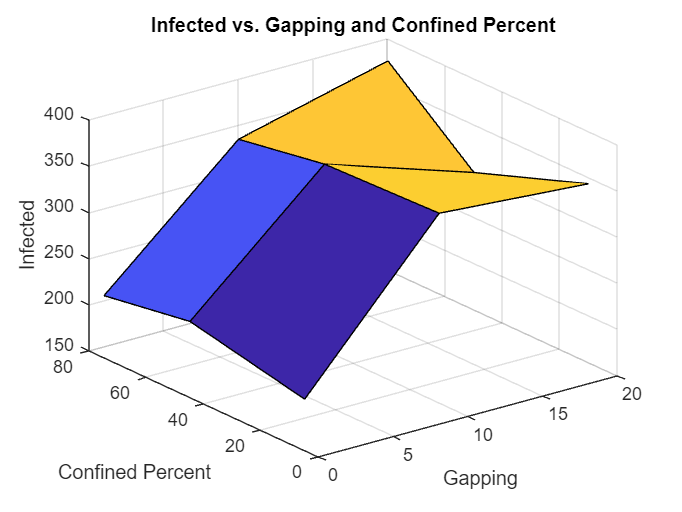

## 9. Extra Exercise (Optional)